 clear all;
close all;

## In this script, you need to implement three functions as part of the k-means algorithm.

These steps will be repeated until the algorithm converges:

  % 1. initialize_centroids
  % This function sets the initial values of the centroids
  
  % 2. assign_vector_to_centroid
  % This goes through the collection of all vectors and assigns them to
  % centroid based on norm/distance
  
  % 3. update_centroids
  % This function updates the location of the centroids based on the collection
  % of vectors (handwritten digits) that have been assigned to that centroid.

## Initialize Data Set

These next lines of code read in two sets of MNIST digits that will be used for training and testing respectively.

% training set (1500 images)
train=csvread('mnist_train_1500.csv');
trainsetlabels = train(:,785);
train=train(:,1:784);
train(:,785)=zeros(1500,1);

% testing set (200 images with 11 outliers)
test=csvread('mnist_test_200_woutliers.csv');
% store the correct test labels
correctlabels = test(:,785);
test=test(:,1:784);

% now, zero out the labels in "test" so that you can use this to assign
% your own predictions and evaluate against "correctlabels"
% in the 'cs1_mnist_evaluate_test_set.m' script
test(:,785)=zeros(200,1);

## After initializing, you will have the following variables in your workspace:

1. train (a 1500 x 785 array, containins the 1500 training images) 2. test (a 200 x 785 array, containing the 200 testing images) 3. correctlabels (a 200 x 1 array containing the correct labels (numerical meaning) of the 200 test images

## To visualize an image, you need to reshape it from a 784 dimensional array into a 28 x 28 array.

to do this, you need to use the reshape command, along with the transpose operation. For example, the following lines plot the first test image

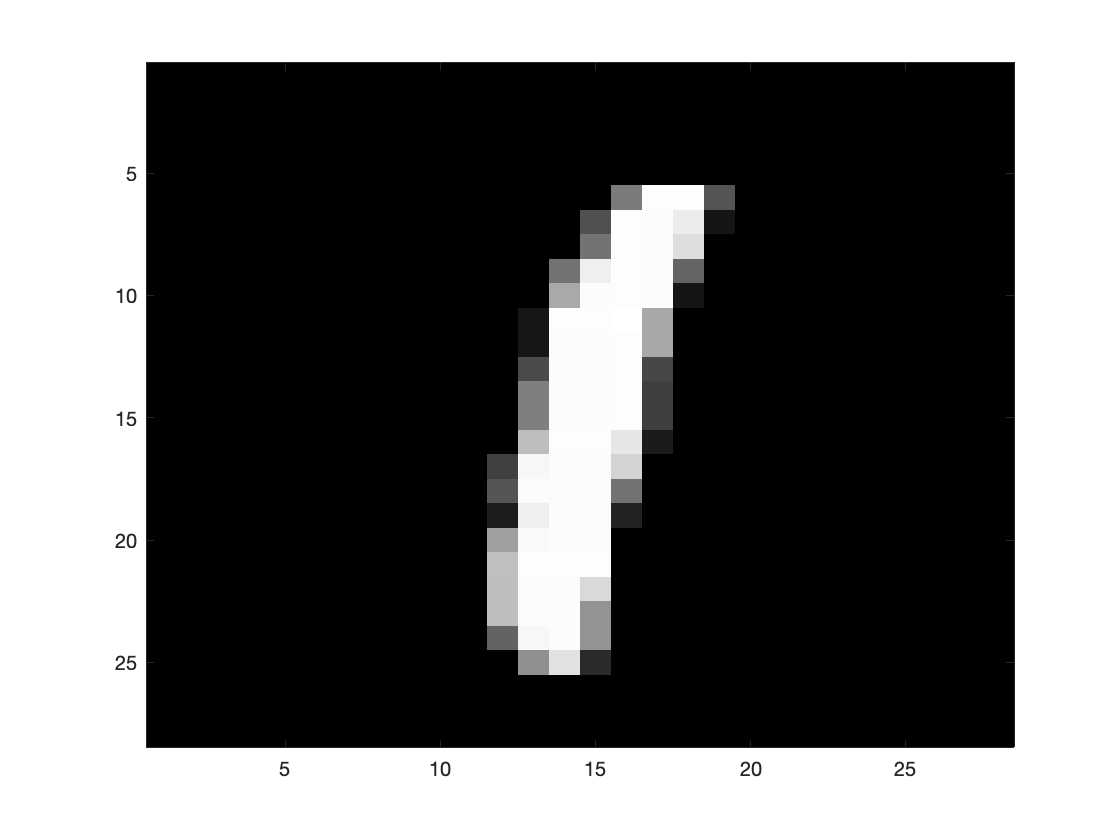

figure;
colormap('gray'); % this tells MATLAB to depict the image in grayscale
testimage = reshape(test(1, [1:784]), [28 28]);
% we are reshaping the first row of 'test', columns 1-784 (since the 785th
% column is going to be used for storing the centroid assignment.
imagesc(testimage'); % this command plots an array as an image.  Type 'help imagesc' to learn more.

## After importing, the array 'train' consists of 1500 rows and 785 columns.

Each row corresponds to a different handwritten digit (28 x 28 = 784) plus the last column, which is used to index that row (i.e., label which cluster it belongs to. Initially, this last column is set to all zeros, since there are no clusters yet established.

## This next section of code calls the three functions you are asked to specify

k= 15; % set k
max_iter= 2000; % set the number of iterations of the algorithm

## The next line initializes the centroids. Look at the initialize_centroids()

function, which is specified further down this file.

centroids=initialize_centroids(train,k);

## Initialize an array that will store k-means cost at each iteration

cost_iteration = zeros([max_iter,1]);

## This for-loop enacts the k-means algorithm

iterUsed = max_iter;
for iter=1:max_iter
    for j=1:size(train,1)
        [index,vec_distance] = assign_vector_to_centroid(train(j,:),centroids);
        cost_iteration(iter) = cost_iteration(iter) + vec_distance;
        train(j,785) = index;
    end
    new_centroids = update_Centroids(train,k);



    if(centroids(:,1:784)==new_centroids)
        fprintf("Converged, iteration %d",iter)
        iterUsed = iter;
        break;
    end

 
    centroids(:,1:784) = new_centroids;
end

Converged, iteration 27

## This section of code plots the k-means cost as a function of the number

of iterations

cost_iteration

cost_iteration = 	1.0e+06 *

    3.0563
    2.3758
    2.3376
    2.3185
    2.3064
    2.2965
    2.2891
    2.2840
    2.2790
    2.2755


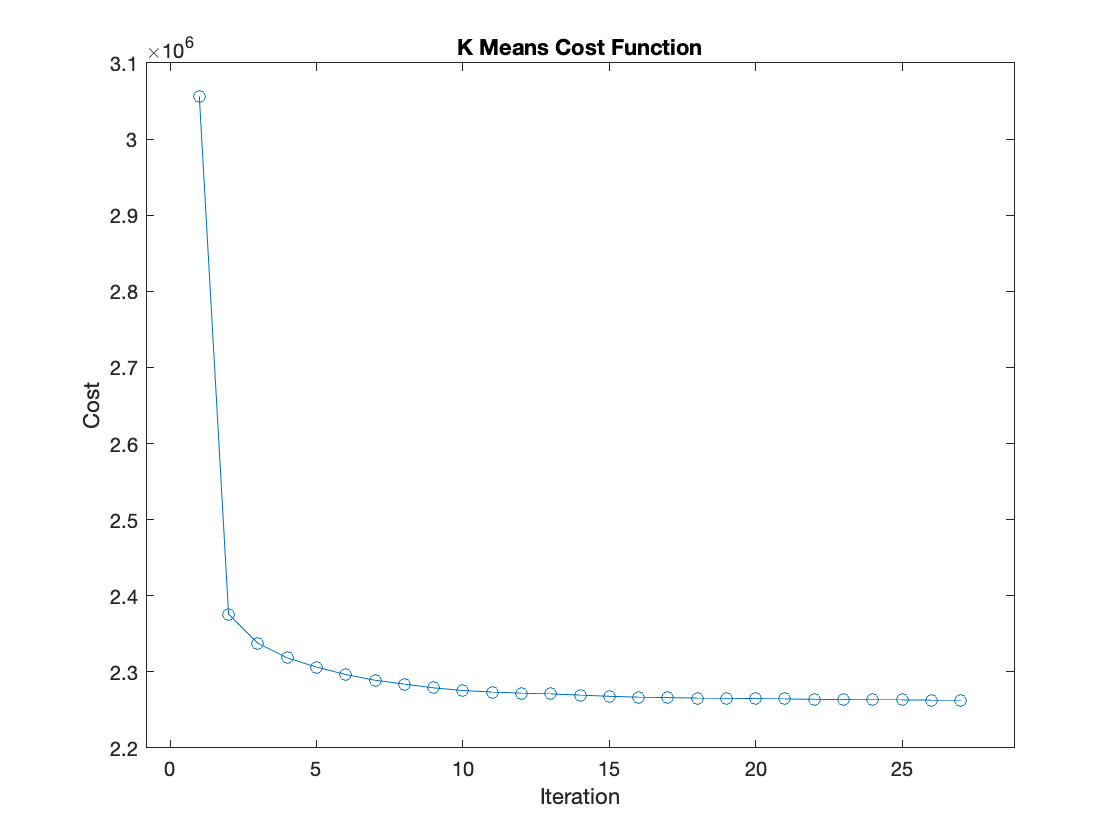

figure;
plot(cost_iteration(1:iterUsed),'o-')
title("K Means Cost Function")
xlabel("Iteration")
ylabel("Cost")
axis padded

## This next section of code will make a plot of all of the centroids

Again, use help [functionname](about:blank<#functionname>) to learn about the different functions that are being used here.

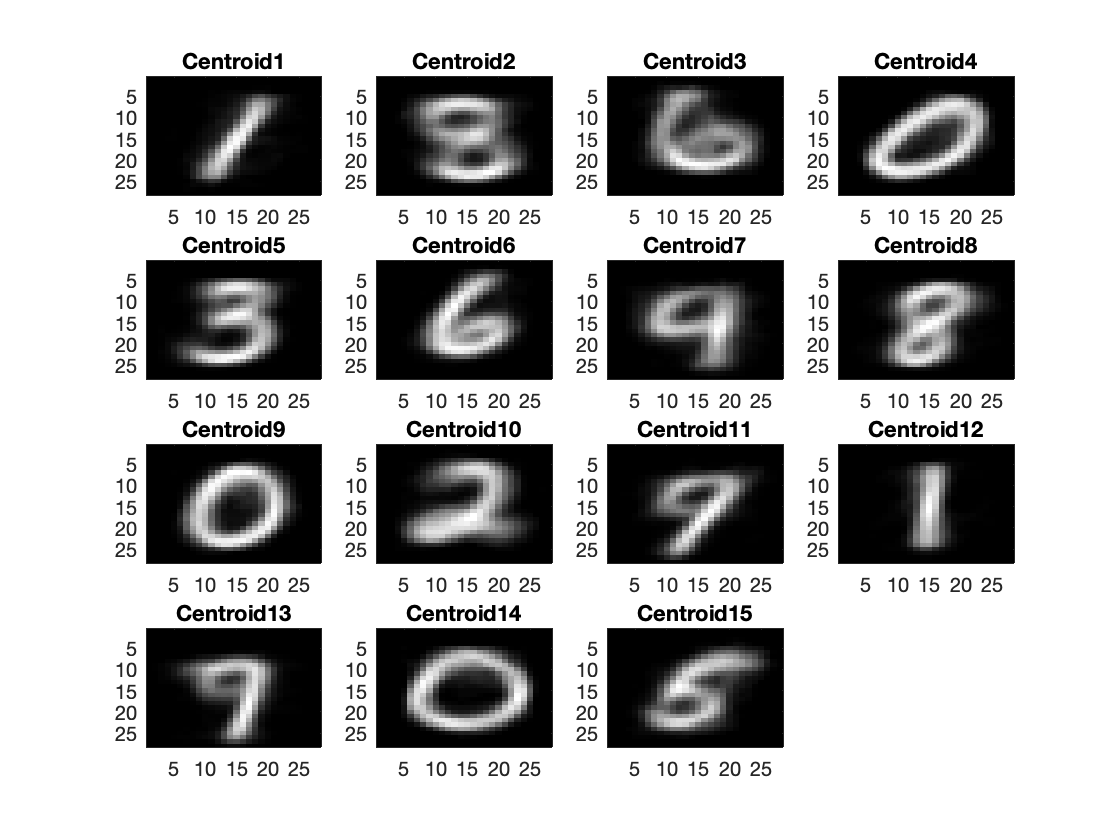

figure;
colormap('gray');

plotsize = ceil(sqrt(k));

for ind=1:k
    
    centr=centroids(ind,[1:784]);
    subplot(plotsize,plotsize,ind);
    
    imagesc(reshape(centr,[28 28])');
    title(strcat('Centroid ',num2str(ind)))

end

## Function to initialize the centroids

This function randomly chooses k vectors from our training set and uses them to be our initial centroids There are other ways you might initialize centroids. *Feel free to experiment.*** Note that this function takes two inputs and emits one output (y).

function y=initialize_centroids(data,num_centroids)

random_index=randperm(size(data,1));

centroids=data(random_index(1:num_centroids),:);

y=centroids;

end

## Function to pick the Closest Centroid using norm/distance

This function takes two arguments, a vector and a set of centroids It returns the index of the assigned centroid and the distance between the vector and the assigned centroid.

function [index, vec_distance] = assign_vector_to_centroid(data,centroids)
    minC = 1;
    dists = zeros([size(centroids,1),1]);
    for c=1:size(centroids,1)
        dists(c) = norm(data(1:784)-centroids(c,1:784));
        if(dists(minC)>dists(c))
            minC = c;
        end
    end
    index = minC;
    vec_distance = dists(minC);
end

## Function to compute new centroids using the mean of the vectors currently assigned to the centroid.

This function takes the set of training images and the value of k. It returns a new set of centroids based on the current assignment of the training images.

function new_centroids=update_Centroids(data,K)
    new_centroids = splitapply(@mean,data(:,1:784),data(:,785));
end